## Point 1

Derive the expression of the gravity vector $g(q)$ of 4R plar robot

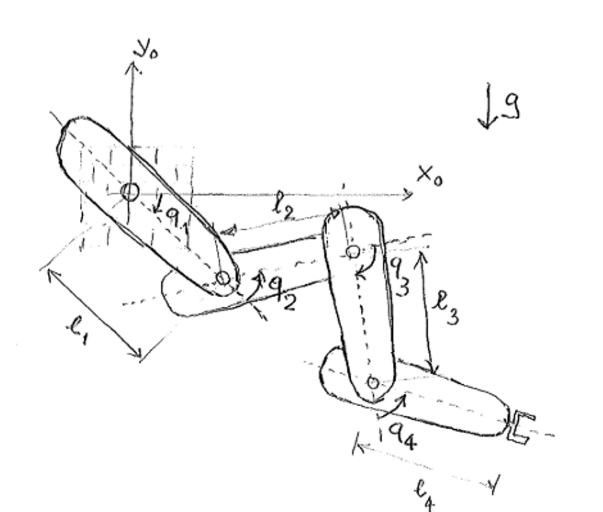

syms q1 q2 q3 q4 real
syms m1 m2 m3 m4 g0 positive
syms d1 d2 d3 d4 positive
syms l1 l2 l3 l4 positive
syms dq1 dq2 dq3 dq4 real

U1 = m1*g0*d1*sin(q1);
U2 = m2*g0*(l1*sin(q1)+d2*sin(q1+q2));
U3 = m3*g0*(l1*sin(q1)+l2*sin(q1+q2)+d3*sin(q1+q2+q3));
U4 = m4*g0*(l1*sin(q1)+l2*sin(q1+q2)+l3*sin(q1+q2+q3)+d4*sin(q1+q2+q3+q4));

U = [U1+U2+U3+U4];
U_test = g0*((m1*d1+(m2+m3+m4)*l1)*sin(q1)+(m2*d2+(m3+m4)*l2)*sin(q1+q2)+(m3*d3+l3*m4)*sin(q1+q2+q3)+d4*m4*sin(q1+q2+q3+q4));
g_q = simplify([diff(U_test,q1); diff(U_test,q2); diff(U_test,q3); diff(U_test,q4);], Steps=100);

disp('Potential Energy: ');

Potential Energy: 


disp(U);

$$\begin{array}{l} g_{0}\,m_{4}\,\left(d_{4}\,\sin\left(q_{1}+q_{2}+q_{3}+q_{4}\right)+\sigma_{1}+l_{1}\,\sin\left(q_{1}\right)+l_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\right)+g_{0}\,m_{3}\,\left(\sigma_{1}+l_{1}\,\sin\left(q_{1}\right)+d_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\right)+g_{0}\,m_{2}\,\left(d_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)+d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\sin\left(q_{1}+q_{2}\right) \end{array}$$

disp('Gravity terms g(q): ');

Gravity terms g(q): 


disp(g_q);

$$\begin{array}{l} \left(\begin{array}{c} g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left(l_{2}\,\left(m_{3}+m_{4}\right)+d_{2}\,m_{2}\right)+g_{0}\,\cos\left(q_{1}\right)\,\left(d_{1}\,m_{1}+l_{1}\,\left(m_{2}+m_{3}+m_{4}\right)\right)+\sigma_{1}+\sigma_{2}\\ g_{0}\,\cos\left(q_{1}+q_{2}\right)\,\left(l_{2}\,\left(m_{3}+m_{4}\right)+d_{2}\,m_{2}\right)+\sigma_{1}+\sigma_{2}\\ \sigma_{1}+\sigma_{2}\\ \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=g_{0}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\,\left(d_{3}\,m_{3}+l_{3}\,m_{4}\right)\\ \sigma_{2}=d_{4}\,g_{0}\,m_{4}\,\cos\left(q_{1}+q_{2}+q_{3}+q_{4}\right) \end{array}$$

## Point 2

Find all equilibrium configurations of the robot such that $g(q_e)=0$

% qe_sol = solve(g_q == 0, [q1, q2, q3, q4], 'ReturnConditions', true);
% disp('Equilibrium configurations q_e (such that g(q_e) = 0):');
% disp(qe_sol);

## Point 3

Find a linear parametrization of the gravity vector such that the gravity vector vanishes

syms a1 a2 a3 a4 real
a1 = m1*d1 + (m2+m3+m4)*l1;
a2 = m2*d2 + (m3+m4)*l2;
a3 = m3*d3 + (m4)*l3;
a4 = m4*d4;

eq1 = m1*d1 + (m2+m3+m4)*l1==0;
eq2 = m2*d2 + (m3+m4)*l2==0;
eq3 = m3*d3 + (m4)*l3==0;
eq4 = m4*d4==0;

eq1 = a1 == 0;
eq2 = a2 == 0;
eq3 = a3 == 0;
eq4 = a4 == 0;

% Solve the system of equations for d1, d2, d3, d4
sol_d = solve([eq1, eq2, eq3, eq4], [d1, d2, d3, d4]);

disp('Solutions for d1, d2, d3, d4 such that g(q) = 0 for all q:');

Solutions for d1, d2, d3, d4 such that g(q) = 0 for all q:


disp(['d1 = ', char(simplify(sol_d.d1))]);

d1 = []


disp(['d2 = ', char(simplify(sol_d.d2))]);

d2 = []


disp(['d3 = ', char(simplify(sol_d.d3))]);

d3 = []


disp(['d4 = ', char(simplify(sol_d.d4))]);

d4 = []
